clear; clc;

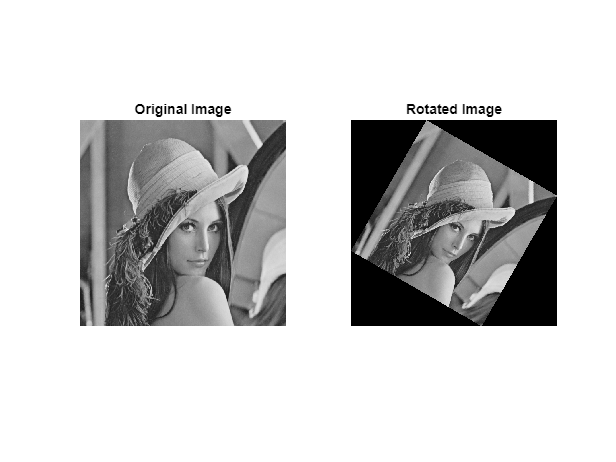

f = imread('Lena.bmp');
g = rotate_image(f, 30);

figure;
subplot(1,2,1);
imshow(f);
title('Original Image');

subplot(1,2,2);
imshow(g);
title('Rotated Image');

## Function

function g = rotate_image(f, theta)
    theta = deg2rad(theta); % Convert to radians for clockwise rotation
    [H, W, ~] = size(f); % Get the size of the input image
    % Calculate the size of the output image
    H0 = abs(H*cos(theta)) + abs(W*sin(theta));
    W0 = abs(H*sin(theta)) + abs(W*cos(theta));
    % Initialize the output image
    g = uint8(zeros(round(H0), round(W0), 3));
    % Calculate the center of the input and output images
    xc = round(W/2); yc = round(H/2);
    x0 = round(W0/2); y0 = round(H0/2);
    % Loop over each pixel in the output image
    for x = 1:W0
        for y = 1:H0
            % Calculate the corresponding point in the input image
            w = (x - x0)*cos(theta) - (y - y0)*sin(theta) + xc;
            z = (x - x0)*sin(theta) + (y - y0)*cos(theta) + yc;
            % Use nearest-neighbor interpolation
            w = round(w); z = round(z);
            % Copy the pixel value if the point is inside the input image
            if w >= 1 && w <= W && z >= 1 && z <= H
                g(y, x, :) = f(z, w, :);
            end
        end
    end
end